# **Wireless Communications**

# **Computer Assignment 2 - Phase 2 - OFDM**

**Soroush Mesforush Mashhad - 810198472**

**Preliminary Definitions**

clc
clear all
N = 2e6;
OFDMBw = 2e7;
Tc = 5e-3;
Td = 1e-5;
L = round(OFDMBw * Td);
CP = L-1;
ncmin = round(OFDMBw * Td);
ncmax = round(OFDMBw * Tc);
nc =round(0.8*ncmax);
Nblock = round(N/nc);

**Part 5)**

SNR_dB = linspace(-10,40,50);
x = 2.*bit_gen(N,2) - 1; % BPSK
PeWater = zeros(length(SNR_dB),1);
Pmax = nc;
for i = 1:length(SNR_dB)
    xblock = zeros(nc,1);
    Y = zeros(nc,1);
    for j=1:Nblock
        h = sqrt(1/2).*(randn(L,1)+1j*randn(L,1));
        N0 = Pmax./(10.^(SNR_dB(i)/10).*nc);
        H = fft(h,nc);
        Htilde = abs(H.^2)./N0;
        P = waterfill(Pmax,(1./Htilde)');
        W = sqrt(N0/2)*(randn(2*L+nc-2,1) + 1j*randn(2*L+nc-2,1));
        xblock = x((j-1)*nc+1:j*nc); 
        xblock = xblock.*sqrt(P)'.*exp(-1j.*phase(H)); 
        xifft = ifft(xblock,nc);
        cyclicprefix = xifft((nc-CP):nc-1);
        xifftwithcp = [cyclicprefix;xifft];
        rec = conv(h,xifftwithcp) + W;
        recwithoucp = rec(L:nc+L+1);
        y = fft(recwithoucp,nc);
        Y((j-1)*nc+1:j*nc) = real(y);
    end
    Y(Y>0) = 1;
    Y(Y<0) = -1;
    Err = 0;
    for k=1:N
        if(Y(k)~=x(k))
            Err = Err+1;
        end
    end
    PeWater(i) = Err/N;
end

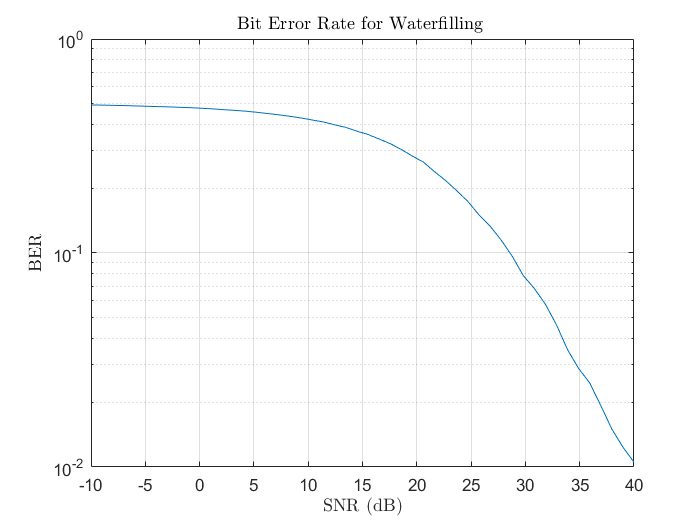

figure
semilogy(SNR_dB,PeWater);
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("BER",'interpreter','latex');
title(" Bit Error Rate for Waterfilling ",'interpreter','latex');

SNR_dB = linspace(-10,40,50);
x = 2.*bit_gen(N,2) - 1; % BPSK
PeWater = zeros(length(SNR_dB),1);
ChannelCap = zeros(length(SNR_dB),1);
Pmax = nc;
for i = 1:length(SNR_dB)
    xblock = zeros(nc,1);
    Y = zeros(nc,1);
    temp = 0;
    for j=1:Nblock
        h = sqrt(1/2).*(randn(L,1)+1j*randn(L,1));
        N0 = Pmax./(10.^(SNR_dB(i)/10).*nc);
        H = fft(h,nc);
        Htilde = abs(H.^2)./N0;
        P = waterfill(Pmax,(1./Htilde)');
        temp = temp + sum(log10( 1+ P'.*abs(H).^2./N0));
        W = sqrt(N0/2)*(randn(2*L+nc-2,1) + 1j*randn(2*L+nc-2,1));
        xblock = x((j-1)*nc+1:j*nc); 
        xblock = xblock.*sqrt(P)'.*exp(-1j.*phase(H)); 
        xifft = ifft(xblock,nc);
        cyclicprefix = xifft((nc-CP):nc-1);
        xifftwithcp = [cyclicprefix;xifft];
        rec = conv(h,xifftwithcp) + W;
        recwithoucp = rec(L:nc+L+1);
        y = fft(recwithoucp,nc);
        Y((j-1)*nc+1:j*nc) = real(y);
    end
    ChannelCap(i) = temp;
end

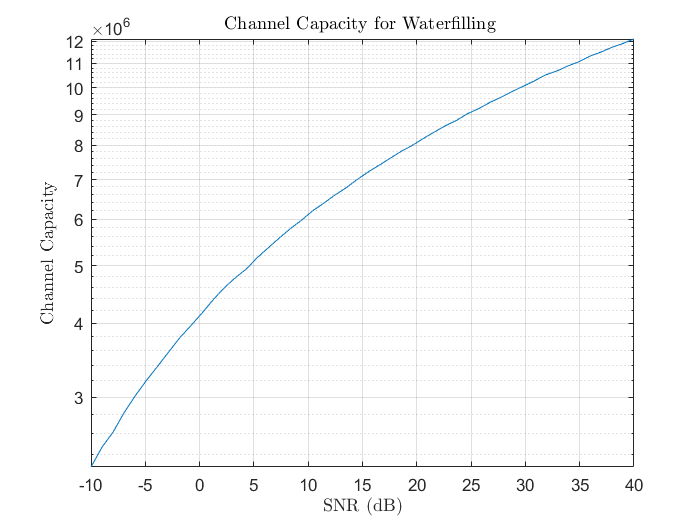

figure
semilogy(SNR_dB,ChannelCap);
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("Channel Capacity",'interpreter','latex');
title(" Channel Capacity for Waterfilling ",'interpreter','latex');

**Part 6)**

M = 10;
SNR_dB = linspace(-10,15,50);
x = 2.*bit_gen(N,2) - 1; % BPSK
PeMRC = zeros(length(SNR_dB),1);
Pmax = sum(x.^2);
    for i = 1:length(SNR_dB)
    xblock = zeros(nc,1);
    Y = zeros(nc,1);
    for j=1:Nblock
         N0 = Pmax./(10.^(SNR_dB(i)/10).*nc);
         xblock = x((j-1)*nc+1:j*nc); 
         xifft = ifft(xblock,nc);
         cyclicprefix = xifft((nc-CP):nc-1);
         xifftwithcp = [cyclicprefix;xifft];
         temp = zeros(nc,1);
        for z=1:M
            h = sqrt(1/2).*(randn(L,1)+1j*randn(L,1));
            H = fft(h,nc);
            W = sqrt(N0/2)*(randn(2*L+nc-2,1) + 1j*randn(2*L+nc-2,1));
            rec = conv(h,xifftwithcp) + W;
            recwithoucp = rec(L:nc+L+1);
            y = fft(recwithoucp,nc);
            y = y.*exp(-1j.*angle(H));
            alph = sqrt(abs(H).^2)./(N0*nc);
            y = alph.*y; 
            temp = temp + y;
        end 
        Y((j-1)*nc+1:j*nc)  = temp;
    end
         Y(Y>0) = 1;
         Y(Y<0) = -1;
         Err = 0;
         for k=1:N
           if(Y(k)~=x(k))
            Err = Err+1;
           end
         end
         PeMRC(i) = Err/N;
    end


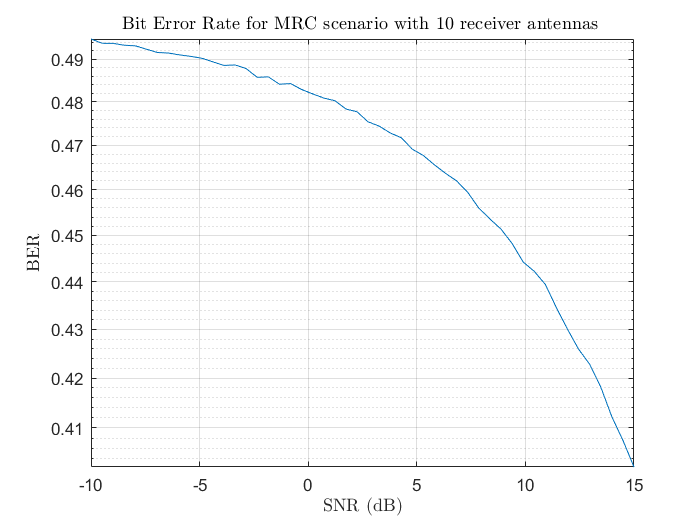

figure
semilogy(SNR_dB,PeMRC);
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("BER",'interpreter','latex');
title(" Bit Error Rate for MRC scenario with 10 receiver antennas ",'interpreter','latex');

**Part 7)**

**Zero Forcing**

SNR_dB = linspace(-10,40,50);
x = 2.*bit_gen(N,2) - 1; % BPSK
Pezf = zeros(length(SNR_dB),1);
Pmax = sum(x.^2);
for i = 1:length(SNR_dB)
    xblock = zeros(nc,1);
    Y = zeros(nc,1);
    for j=1:Nblock
        N0 = Pmax./(10.^(SNR_dB(i)/10).*nc);
        h = sqrt(1/2).*(randn(L,1)+1j*randn(L,1));
        H = fft(h,nc);
        W = sqrt(N0/2)*(randn(2*L+nc-2,1) + 1j*randn(2*L+nc-2,1));
        xblock = x((j-1)*nc+1:j*nc); 
        xifft = ifft(xblock,nc);
        cyclicprefix = xifft((nc-CP):nc-1);
        xifftwithcp = [cyclicprefix;xifft];
        rec = conv(h,xifftwithcp) + W;
        recwithoucp = rec(L:nc+L+1);
        y = fft(recwithoucp,nc);
        y = (y./H);
        Y((j-1)*nc+1:j*nc) = real(y);
    end
    Y(Y>0) = 1;
    Y(Y<0) = -1;
    Err = 0;
    for k=1:N
        if(Y(k)~=x(k))
            Err = Err+1;
        end
    end
    Pezf(i) = Err/N;
end

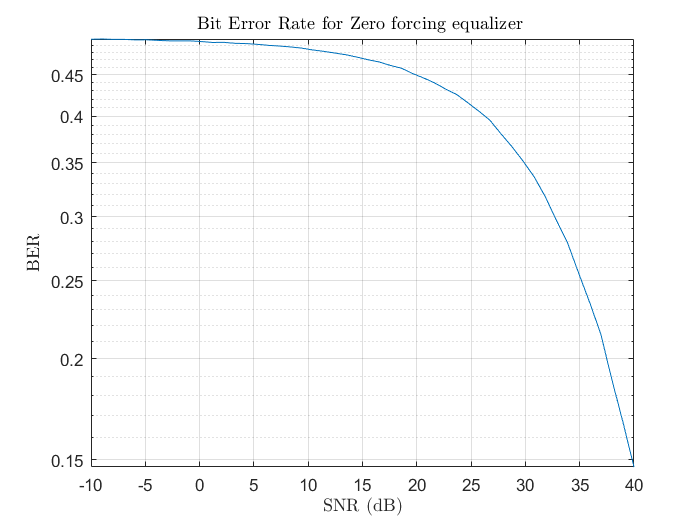

figure
semilogy(SNR_dB,Pezf);
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("BER",'interpreter','latex');
title(" Bit Error Rate for Zero forcing equalizer ",'interpreter','latex');

**MMSE**

SNR_dB = linspace(-10,40,50);
x = 2.*bit_gen(N,2) - 1; % BPSK
PeMMSE = zeros(length(SNR_dB),1);
Pmax = sum(x.^2);
for i = 1:length(SNR_dB)
    xblock = zeros(nc,1);
    Y = zeros(nc,1);
    for j=1:Nblock
        N0 = Pmax./(10.^(SNR_dB(i)/10).*nc);
        h = sqrt(1/2).*(randn(L,1)+1j*randn(L,1));
        H = fft(h,nc);
        W = sqrt(N0/2)*(randn(2*L+nc-2,1) + 1j*randn(2*L+nc-2,1));
        xblock = x((j-1)*nc+1:j*nc); 
        xifft = ifft(xblock,nc);
        cyclicprefix = xifft((nc-CP):nc-1);
        xifftwithcp = [cyclicprefix;xifft];
        rec = conv(h,xifftwithcp) + W;
        recwithoucp = rec(L:nc+L+1);
        y = fft(recwithoucp,nc);
        y = y.*(conj(H)./(abs(H).^2 + N0/nc));
        Y((j-1)*nc+1:j*nc) = real(y);
    end
    Y(Y>0) = 1;
    Y(Y<0) = -1;
    Err = 0;
    for k=1:N
        if(Y(k)~=x(k))
            Err = Err+1;
        end
    end
    PeMMSE(i) = Err/N;
end

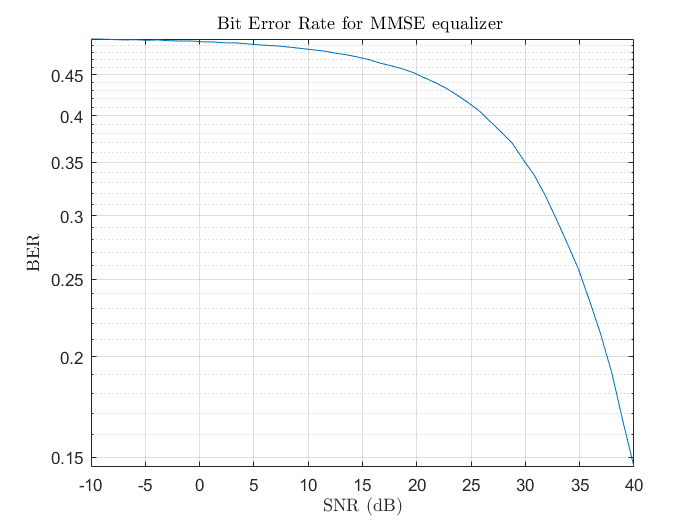

figure
semilogy(SNR_dB,PeMMSE );
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("BER",'interpreter','latex');
title(" Bit Error Rate for MMSE equalizer ",'interpreter','latex');

**Part 8 )**

SNR_dB = linspace(-10,40,50);
x = 2.*bit_gen(N,2) - 1; % BPSK
PeMMSEClip = zeros(length(SNR_dB),1);
Pmax = sum(x.^2);
for i = 1:length(SNR_dB)
    xblock = zeros(nc,1);
    Y = zeros(nc,1);
    for j=1:Nblock
        N0 = Pmax./(10.^(SNR_dB(i)/10).*nc);
        h = sqrt(1/2).*(randn(L,1)+1j*randn(L,1));
        H = fft(h,nc);
        W = sqrt(N0/2)*(randn(2*L+nc-2,1) + 1j*randn(2*L+nc-2,1));
        xblock = x((j-1)*nc+1:j*nc); 
        xifft = ifft(xblock,nc);
        Mk = max(abs(xifft));
        M = 0.4*abs(Mk);
        for z=1:length(xifft)
            if abs(xifft(z))>=M
                xifft(z) = xifft(z).*M./(abs(xifft(z)));
            end
        end
        cyclicprefix = xifft((nc-CP):nc-1);
        xifftwithcp = [cyclicprefix;xifft];
        rec = conv(h,xifftwithcp) + W;
        recwithoucp = rec(L:nc+L+1);
        y = fft(recwithoucp,nc);
        y = y.*(conj(H)./(abs(H).^2 + N0/nc));
        Y((j-1)*nc+1:j*nc) = real(y);
    end
    Y(Y>0) = 1;
    Y(Y<0) = -1;
    Err = 0;
    for k=1:N
        if(Y(k)~=x(k))
            Err = Err+1;
        end
    end
    PeMMSEClip(i) = Err/N;
end

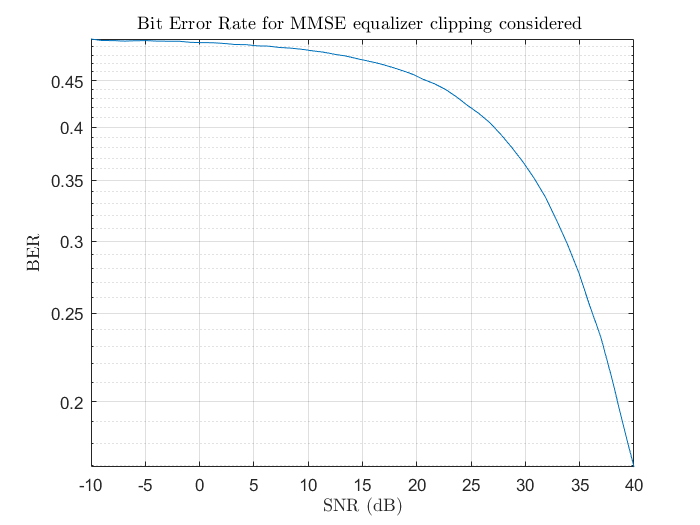

figure
semilogy(SNR_dB,PeMMSEClip );
grid on
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("BER",'interpreter','latex');
title(" Bit Error Rate for MMSE equalizer clipping considered ",'interpreter','latex');

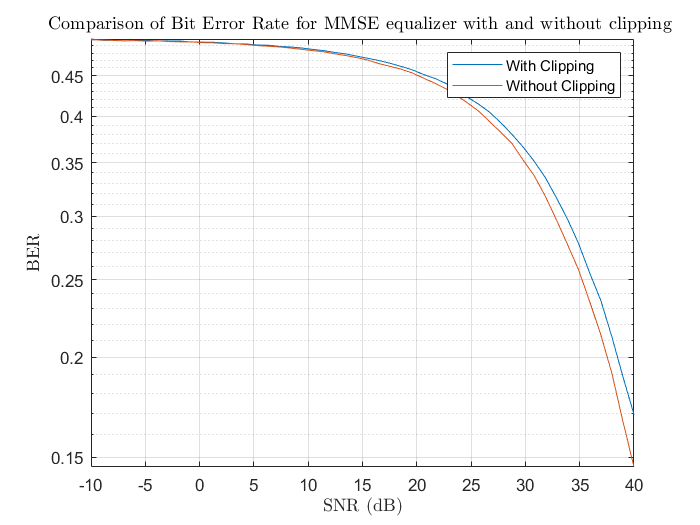

figure
semilogy(SNR_dB,PeMMSEClip,SNR_dB,PeMMSE);
xlabel(" SNR (dB)",'interpreter','latex');
ylabel("BER",'interpreter','latex');
title("Comparison of Bit Error Rate for MMSE equalizer with and without clipping ",'interpreter','latex');
legend('With Clipping','Without Clipping')
grid on